# Mathematical Morphology

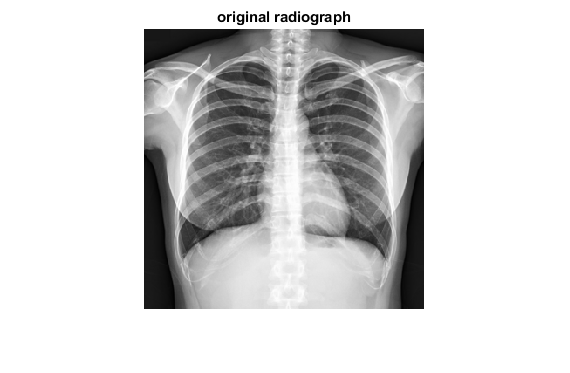

%image preparation for processing skeleton
f=imread('radiograph1.jpg'); %import the image 
f=double(f(:,:,1));
f=f/max(max(f));
f=imresize(f,0.25); %define the image size 
figure(1)
imshow(f,[]), title('original radiograph');

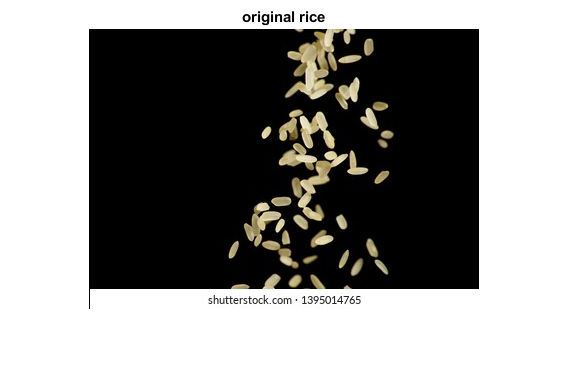


%image preparation 'rice'
f2=imread('rice.jpg');
%f2=f2/max(max(f2));
%f2=imresize(f2,0.25); %define the image size 
figure(2)
imshow(f2,[]), title('original rice');

## Dilatation

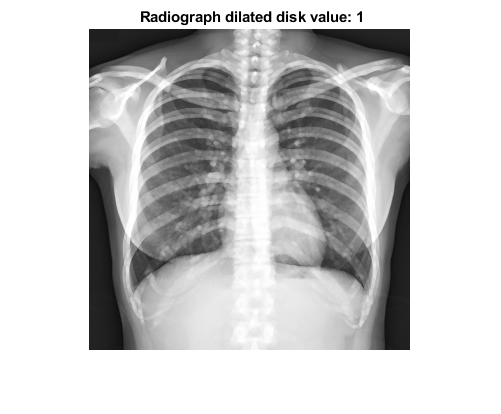

%skeleton
se = strel('disk',1); %define el valor estructural de los pixeles que componen la imagen, el valor asignado afecta el resultado (entre menor valor más definido)
BW2 = imdilate(f,se);%dilata los pixeles de la imagen para hacerlos ver más o menos borrosos
imshow(BW2), title(' Radiograph dilated disk value: 1')

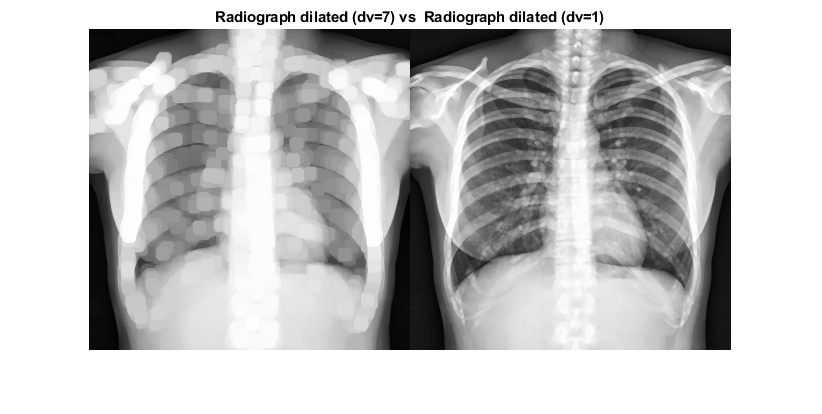


% Use different disk size
se = strel('disk',7); %define el valor estructural de los pixeles que componen la imagen, el valor asignado afecta el resultado (entre menor valor más definido)
BW1 = imdilate(f,se);%dilata los pixeles de la imagen para hacerlos ver más o menos borrosos
imshowpair(BW1,BW2, 'montage'),title('Radiograph dilated (dv=7) vs  Radiograph dilated (dv=1)')

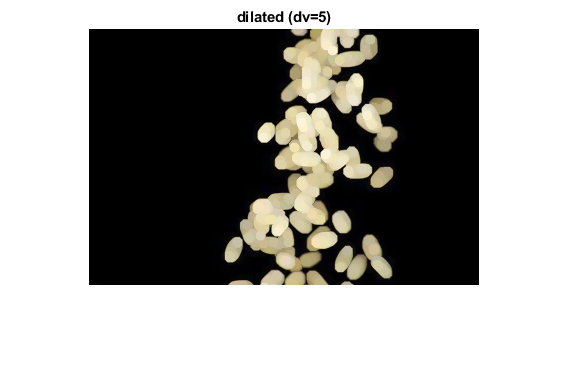


%rice
se2 = strel('disk',5); %function to define the structural value of the pixels that compose an image, the assigned value affects the recults of the image (the lower the value the sharper the image)
BW22 = imdilate(f2,se2);%dilatates the image 
imshow(BW22), title('dilated (dv=5)')

## Erosion

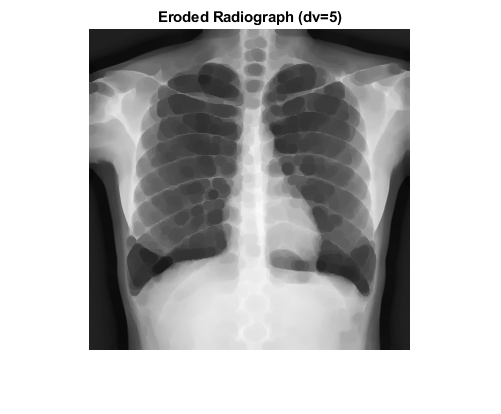

%skeleton
se = strel('disk',5); %define the structural value of pixels 
BW3 = imerode(f,se); %erosion de los pixeles estructurales de la imagen 
imshow(BW3), title('Eroded Radiograph (dv=5)')

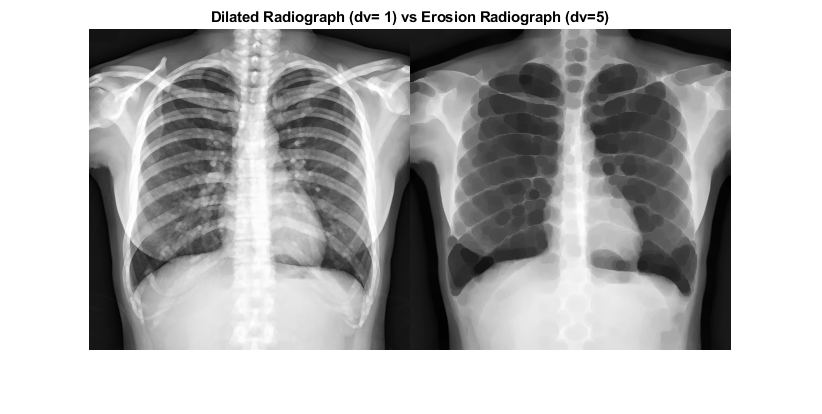


% Use different disk size
imshowpair(BW2,BW3, 'montage'),title('Dilated Radiograph (dv= 1) vs Erosion Radiograph (dv=5)')

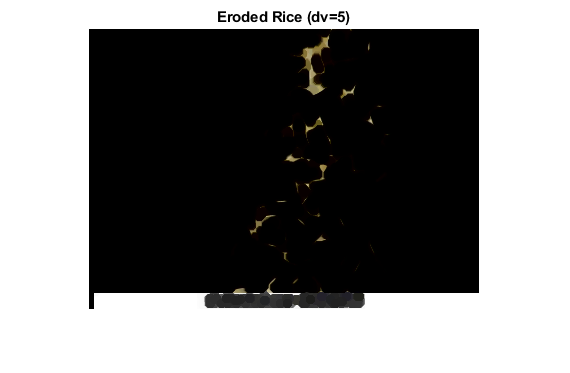


%rice 
se3 = strel('disk',5); %define the structural value of pixels 
BW33 = imerode(f2,se); %erosion de los pixeles estructurales de la imagen 
imshow(BW33), title('Eroded Rice (dv=5)')

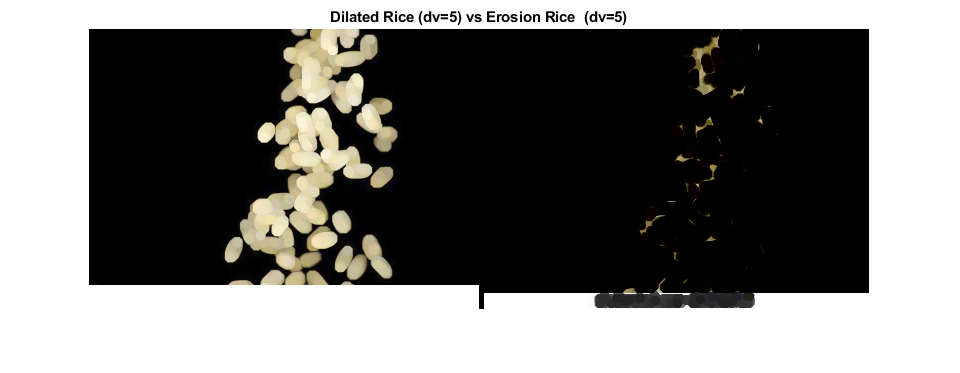

% Use different disk size
imshowpair(BW22,BW33, 'montage'),title('Dilated Rice (dv=5) vs Erosion Rice  (dv=5)')

## Opening

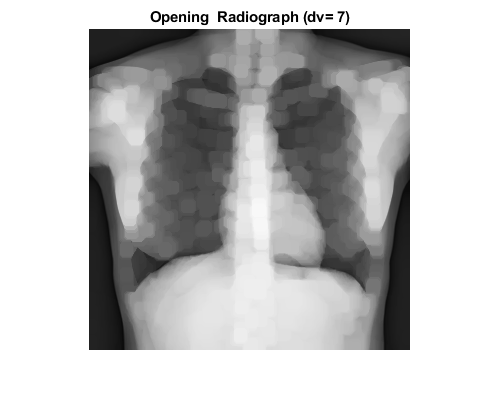

se = strel('disk',7);%mayor el opening más blurry se ve 
BW2 = imopen(f,se);
imshow(BW2), title('Opening  Radiograph (dv= 7)')

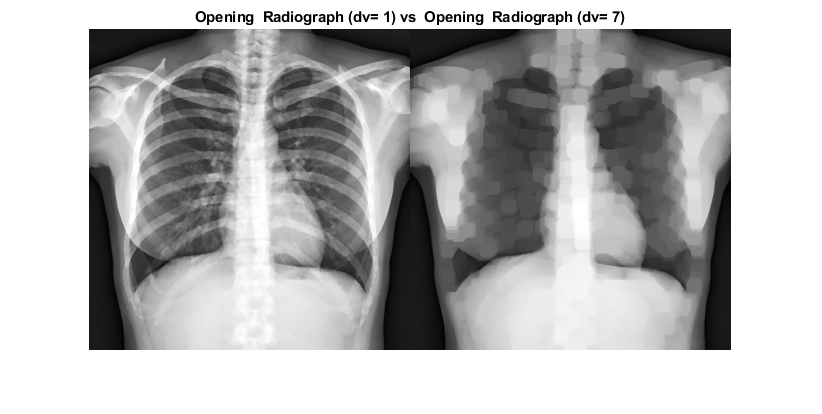


% Use different disk size
se4 = strel('disk',1);%mayor el opening más blurry se ve 
BW1 = imopen(f,se4);
imshowpair(BW1,BW2, 'montage'),title('Opening  Radiograph (dv= 1) vs  Opening  Radiograph (dv= 7)')

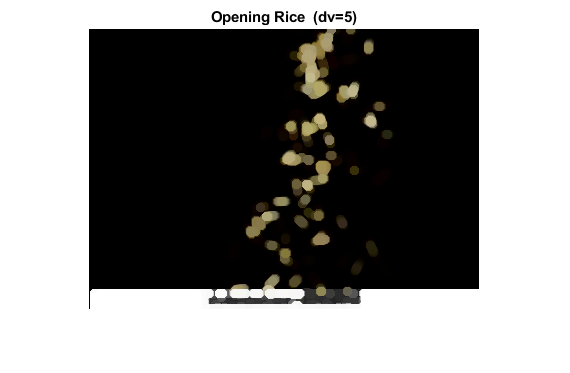

%imshow(BW2), title('Opening  Radiograph (disk size 3)')

%rice 
se6 = strel('disk',5); %define the structural value of pixels 
BW33 = imopen(f2,se6); %erosion de los pixeles estructurales de la imagen 
imshow(BW33), title('Opening Rice  (dv=5)')

## Closing

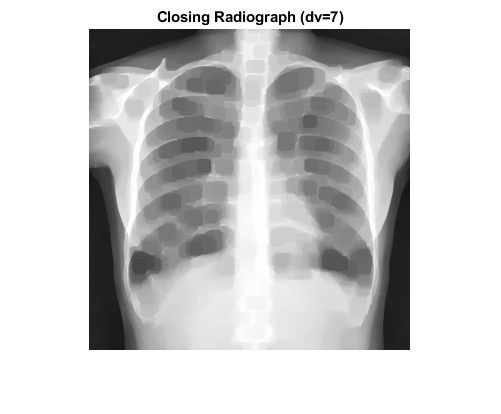

se = strel('disk',7);
BW2 = imclose(f,se);
imshow(BW2), title('Closing Radiograph (dv=7)')

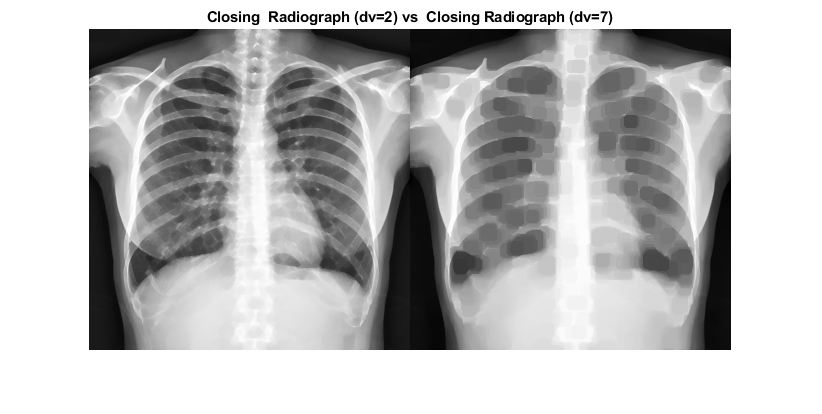


% Use different disk size
se5 = strel('disk',2);
BW1 = imclose(f,se5);
imshowpair(BW1,BW2, 'montage'),title('Closing  Radiograph (dv=2) vs  Closing Radiograph (dv=7)')

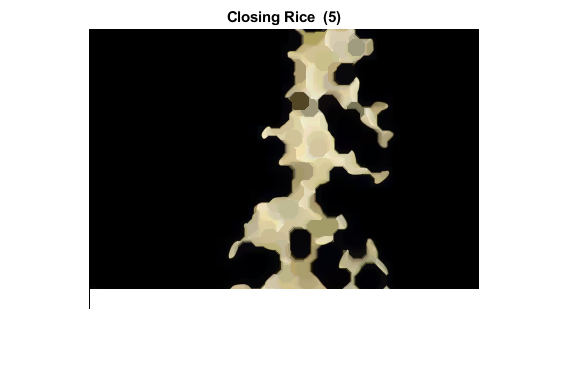

%imshow(BW2), title('Closing  Radiograph (disk size 2)')

%rice
se7 = strel('disk',9); %define the structural value of pixels 
BW33 = imclose(f2,se7); %closing de los pixeles estructurales de la imagen 
imshow(BW33), title('Closing Rice  (dv=5)')

## Gradient

se = strel('disk',1);
BW1 = imdilate(f,se) - imerode(f,se);
imshow(BW1), title('Gradient')
% Use different disk size


## Preprocess the Image The Rice Matlab Example

Read an image into the workspace.

I = imread('rice.png');
imshow(I)

The background illumination is brighter in the center of the image than at the bottom. Preprocess the image to make the background illumination more uniform.

As a first step, remove all of the foreground (rice grains) using morphological opening. The opening operation removes small objects that cannot completely contain the structuring element. Define a disk-shaped structuring element with a radius of 15, which fits entirely inside a single grain of rice.

se = strel('disk',15)

To perform the morphological opening, use `imopen` with the structuring element.

background = imopen(I,se);
imshow(background)

Subtract the background approximation image, `background`, from the original image, `I`, and view the resulting image. After subtracting the adjusted background image from the original image, the resulting image has a uniform background but is now a bit dark for analysis.

I2 = I - background;
imshow(I2)

Use `imadjust` to increase the contrast of the processed image `I2` by saturating 1% of the data at both low and high intensities and by stretching the intensity values to fill the `uint8` dynamic range.

I3 = imadjust(I2);
imshow(I3)

Note that the prior two steps could be replaced by a single step using `imtophat` which first calculates the morphological opening and then subtracts it from the original image.

`I2 = imtophat(I,strel('disk',15));`

Create a binary version of the processed image so you can use toolbox functions for analysis. Use the `imbinarize` function to convert the grayscale image into a binary image. Remove background noise from the image with the `bwareaopen` function.

bw = imbinarize(I3);
bw = bwareaopen(bw,50);
imshow(bw)

% Use different size of the structural element


# Skeletonize 2-D Grayscale Image

Read a 2-D grayscale image into the workspace. Display the image. Objects of interest are dark threads against a light background.

I = imread('threads.png');
imshow(I)

Skeletonization requires a binary image in which foreground pixels are `1` (white) and the background is `0` (black). To make the original image suitable for skeletonization, take the complement of the image so that the objects are light and the background is dark. Then, binarize the result.

Icomplement = imcomplement(I);
BW = imbinarize(Icomplement);
imshow(BW)

Perform skeletonization of the binary image using `bwskel`.

out = bwskel(BW);

Display the skeleton over the original image by using the `labeloverlay` function. The skeleton appears as a 1-pixel wide blue line over the dark threads.

imshow(labeloverlay(I,out,'Transparency',0))

Prune small spurs that appear on the skeleton and view the result. One short branch is pruned from a thread near the center of the image.

out2 = bwskel(BW,'MinBranchLength',15);
imshow(labeloverlay(I,out2,'Transparency',0))
%Play with the size of Min Branch Lenght


## The alternative method with bwmorph

BW3 = bwmorph(BW,'skel',Inf);
figure
imshow(BW3)

## Lets play with the x-ray

se = strel('disk',7);
BW3 = f-imopen(f,se);
imshow(BW3,[])
bw = imbinarize(BW3);
imshow(bw,[])
bw = imopen(bw,strel('disk',1));
bw = imclose(bw,strel('disk',3));
imshow(bw,[])
bw = bwareaopen(bw,50);
imshow(bw,[])
BW3 = bwmorph(bw,'skel',Inf);
imshow(BW3)
imshow(labeloverlay(f,BW3,'Transparency',0))

% Do the same with your own image